load ./matlab_data/my_sine_new2.mat
load ./matlab_data/official_sine_new2.mat

AMPLITUDE = 2;

[my_error_y, my_error_phi, desired_phi_dot] = get_sine_info_2(my_sine, AMPLITUDE);
[of_error_y, of_error_phi, desired_phi_dot2] = get_sine_info_2(official_sine, AMPLITUDE);

my_input = [my_sine(:,7), desired_phi_dot];
my_output = [my_error_y, my_error_phi, my_sine(:,8)];

my_input2 = [official_sine(:,7), desired_phi_dot2];
my_output2 = [of_error_y, of_error_phi, official_sine(:,8)];

load ./matlab_data/discrete_model_2.mat

uncer_ss = get_uncertain_ss(ss1);

T = 0.0333;
order = size(uncer_ss.A, 1);
robust_system_A = uncer_ss.A;
robust_system_B = [uncer_ss.B(:,2), uncer_ss.B(:,1)];
robust_system_C = [uncer_ss.C(1:2,:);uncer_ss.C; zeros([1, order])];
robust_system_D = [[0;0;0;0;0;1],zeros(6,1)];
robust_ss = ss(robust_system_A, robust_system_B, robust_system_C, robust_system_D, T);
robust_ss.InputName = {'road_dist';'steering_angle'};
robust_ss.OutputName = {'error_y';'error_phi';'output_y';'output_phi';'output_omega';'output_dist'};

W_dist = ss(1); W_dist.u = 'd4';W_dist.y = 'y_4_noise';
W_omega = ss(0.1); W_omega.u = 'd3';W_omega.y = 'y_3_noise';
W_phi = ss(1); W_phi.u = 'd2';W_phi.y = 'y_2_noise';
W_y = ss(1); W_y.u = 'd1';W_y.y = 'y_1_noise';
Wact = 10 * c2d(tf([1,1],[1,15]),T);  Wact.u = 'steering_angle';  Wact.y = 'diff_u';
%Wact = ss(1);  Wact.u = 'steering_angle';  Wact.y = 'diff_u';
Wcosty = ss(150); Wcosty.u = 'error_y';Wcosty.y = 'e1';
Wcostphi = ss(5); Wcostphi.u = 'error_phi';Wcostphi.y = 'e2';

y_meas = sumblk('y1=y_1_noise+output_y');
phi_meas = sumblk('y2 = y_2_noise + output_phi');
omega_meas = sumblk('y3 = y_3_noise + output_omega');
dist_meas = sumblk('y4 = y_4_noise + output_dist');

ICinputs = {'d1';'d2';'d3';'d4';'road_dist';'steering_angle'};
ICoutputs = {'e1';'e2';'diff_u';'y1';'y2';'y3';'y4'};
wholess = connect(robust_ss,W_dist, W_phi, W_y, Wcosty, Wcostphi,Wact, W_omega,...
                 y_meas,phi_meas, dist_meas, omega_meas,ICinputs,ICoutputs);

nmeas = 4;
ncont = 1;
[K, CL, gamma] = hinfsyn(wholess,nmeas,ncont);
gamma

gamma = 141.6383

KA = K.A; KB = K.B; KC = K.C; KD = K.D;
K


K =
 
  A = 
               x1          x2          x3          x4          x5
   x1       1.026      0.0574    -0.01815     0.03348  -2.194e-08
   x2      0.5202       1.056       0.122     0.03683  -1.289e-06
   x3      -16.74      -4.974    -0.02928     -0.3999   3.876e-05
   x4       1.551      0.4442      0.1046        1.03   -3.61e-06
   x5   2.563e+04        8484       801.1       584.8      0.5481
 
  B = 
              u1         u2         u3         u4
   x1     0.1754   -0.01369      1.157     0.1601
   x2    0.05784   0.005599     -4.151    -0.5707
   x3     -1.364    0.06082      18.75      2.385
   x4    0.08429  -0.001518     -2.203    -0.2838
   x5       2322     -154.3       6817      857.7
 
  C = 
               x1          x2          x3          x4          x5
   y1        29.1       9.632      0.9095      0.6639  -6.669e-05
 
  D = 
            u1       u2       u3       u4
   y1    2.636  -0.1752    7.739   0.9737
 
Sample time: 0.0333 seconds
Discrete-time sta

% save("all_current_space_2.mat")
save ./matlab_data/discrete_controller_2.mat KA KB KC KD
% save ./matlab_data/discrete_model_matrix.mat robust_system_A robust_system_B robust_system_C robust_system_D

[K_robust, CL_robust, gamma] = dksyn(wholess,nmeas,ncont);
gamma

gamma = 150.5346

K_robust;

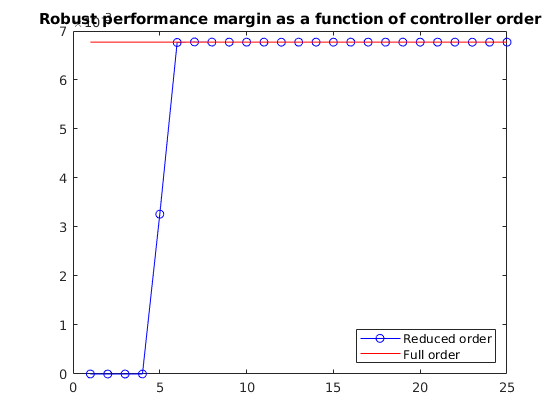

NS = size(K_robust.A, 1);
% NS = order(K_robust); 
StateOrders = 1:NS;
Kred = reduce(K_robust,StateOrders);
% Compute robust performance margin for each reduced controller
CLP = lft(wholess,Kred);
for k=1:NS
   PM(k) = robgain(CLP(:,:,k),gamma);
end

% Compare robust performance of reduced- and full-order controllers
PMfull = PM(end).LowerBound;
plot(StateOrders,[PM.LowerBound],'b-o',...
   StateOrders,repmat(PMfull,[1 NS]),'r');
title('Robust performance margin as a function of controller order')
legend('Reduced order','Full order','location','SouthEast')

K = Kred(:,:,end,1);
% K = K_robust;
KA = K.A; KB = K.B; KC = K.C; KD = K.D;
save("all_current_space_2.mat")
save ./matlab_data/robust_discrete_controller.mat KA KB KC KD
%save ./matlab_data/discrete_model_matrix.mat robust_system_A robust_system_B robust_system_C robust_system_D